load('\\sosiknas1\IFCB_products\SPIROPA\summary\TN368cast_mean_count_biovol_byclass')
group_table = readtable('\\sosiknas1\training_sets\IFCB\config\IFCB_classlist_type.csv');
group_table.CNN_classlist(strmatch('Pseudo-nitzschia', group_table.CNN_classlist)) = {'Pseudo_nitzschia'};
class2use = cast_table_binned.count.Properties.VariableNames';
[~,ia,ib] = intersect(group_table.CNN_classlist, class2use);

cruisestr = 'TN368';
diatom_ind = ib(find(group_table.Diatom(ia)));
dino_ind = ib(find(group_table.Dinoflagellate(ia)));
ciliate_ind = ib(find(group_table.Ciliate(ia)));
cocco_ind = ib(find(group_table.Coccolithophore(ia)));
class_ind = diatom_ind;
castset = {'39' '62' '71' '100' '81' '82'};
castset = {'39' '56' '62' '70' '71' '81' '82' '84' '86' '89' '100'};

%castset = {'41' '43'};
castii_set = find(ismember(cast_table_binned.cast, castset));
cat(1,cast_table_binned.pid{castii_set})
[temp, ss] = sort(sum(cast_table_binned.biovol{castii_set,class_ind}), 'descend');
[class2use(diatom_ind(ss)) cellstr(num2str(temp'))]

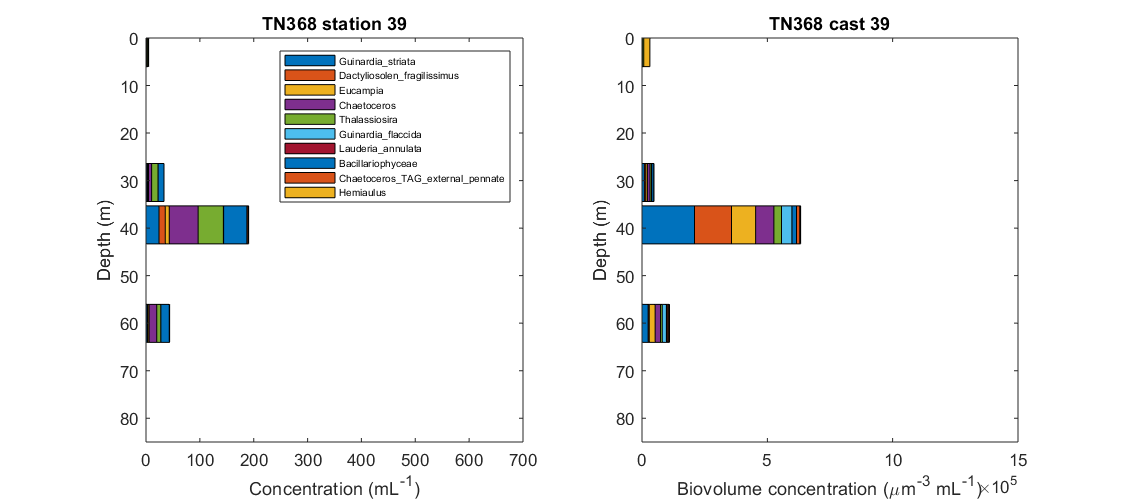

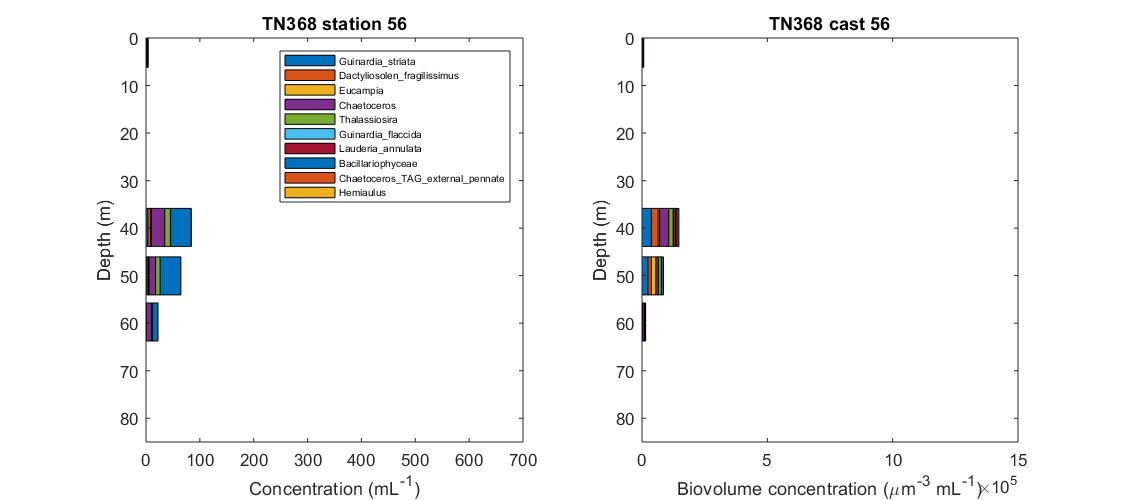

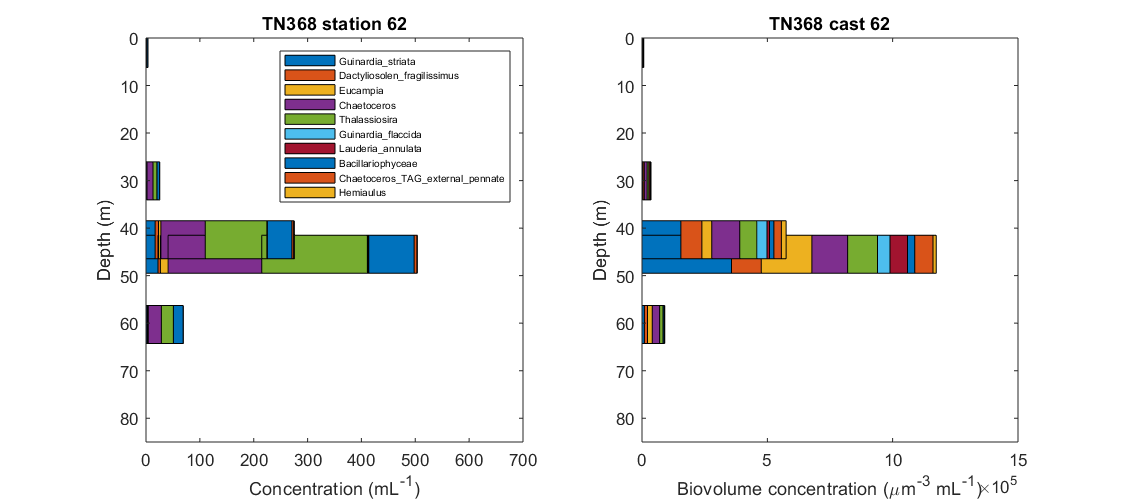

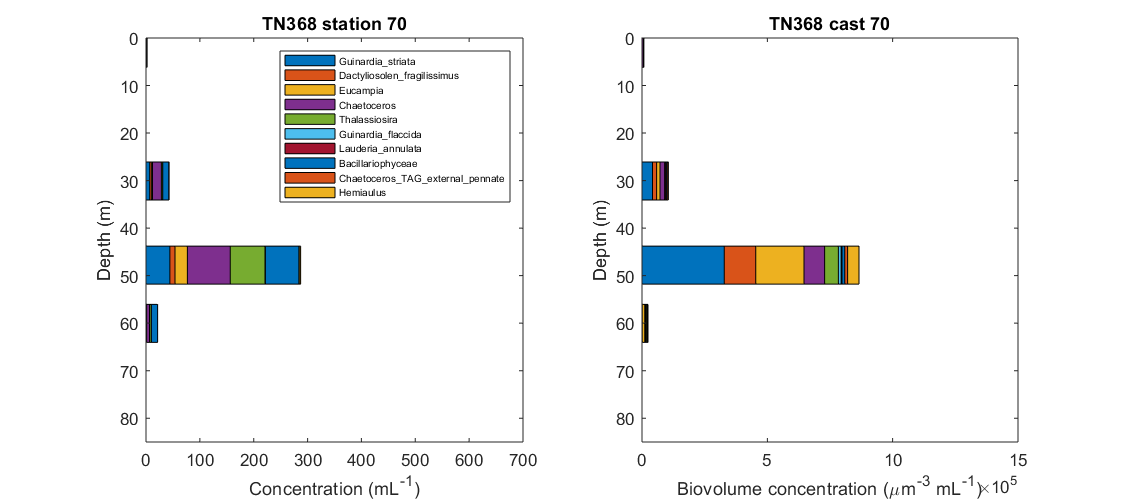

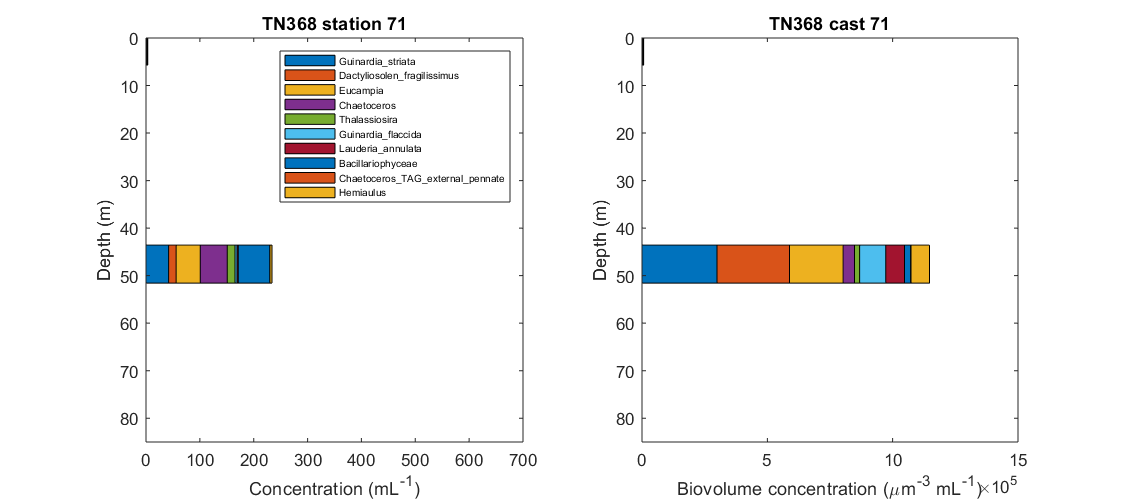

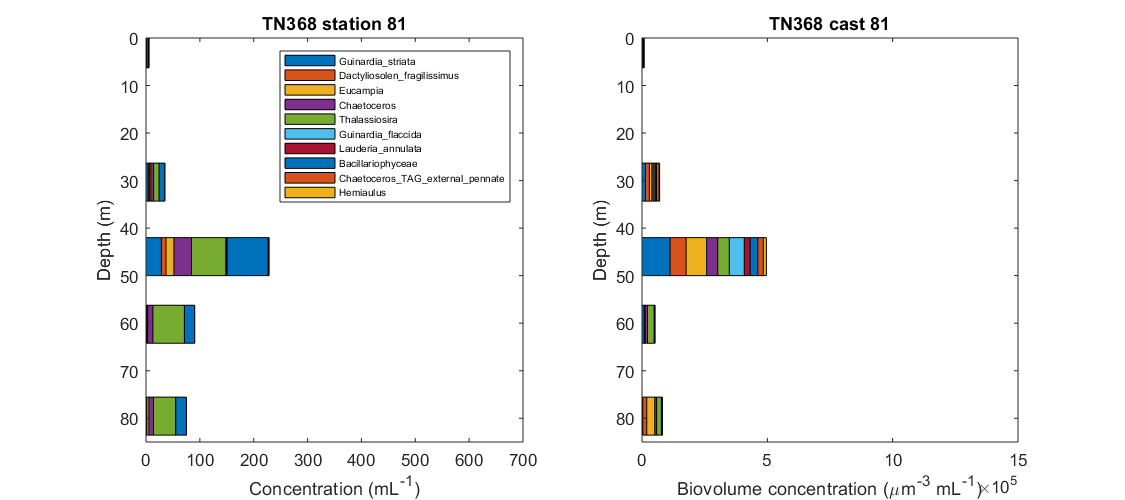

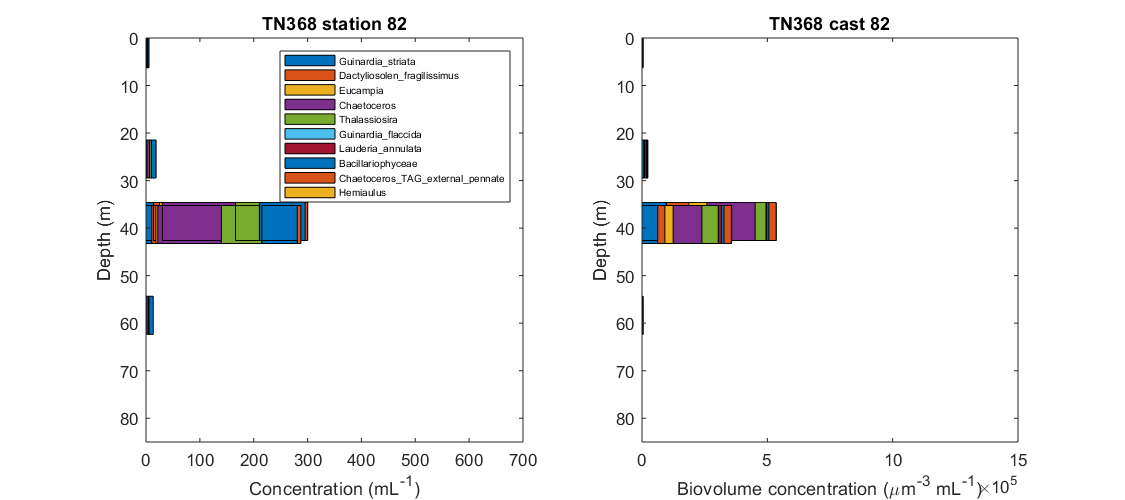

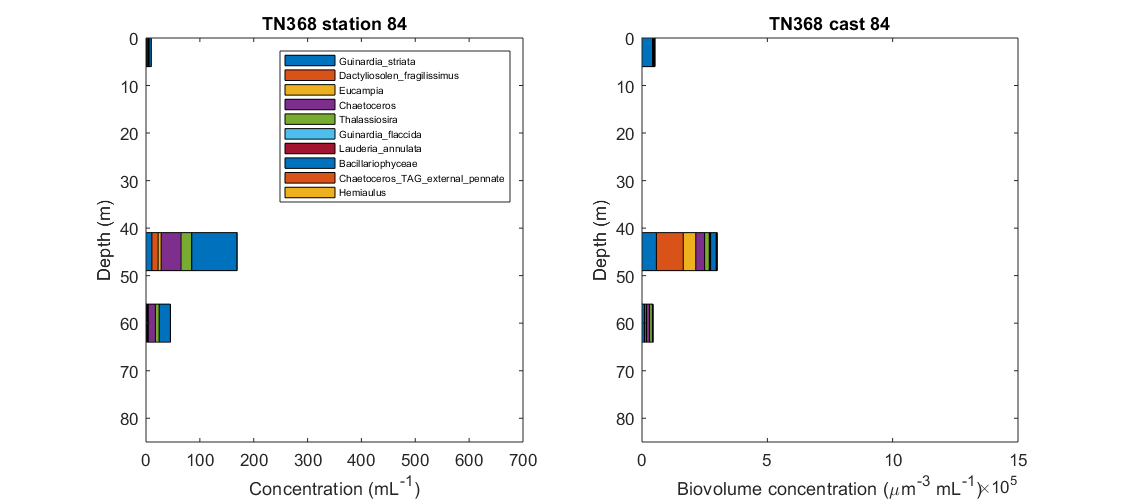

%caststr = '62'; % 39, 62, 71, and 100
for cc = 1:length(castset)
    caststr = castset(cc);
    castii = find(strcmp(cast_table_binned.cast, caststr) & strcmp(cast_table_binned.cruise, cruisestr));
    d = cast_table_binned.depth(castii);
    [d,ids] = sort(cast_table_binned.depth(castii));
    cut = 10;
    figure, set(gcf, 'position', [400 350 900 400])
    subplot(1,2,1)
    if strmatch('86', caststr)
        X = [80 40 1.27];
        barh(X, cast_table_binned.count{castii(ids),diatom_ind(ss(1:cut))}./cast_table_binned.ml_analyzed(castii(ids)), 'stacked', 'barwidth', 8/min(diff(X)));
    else
        barh(cast_table_binned.depth(castii(ids)), cast_table_binned.count{castii(ids),diatom_ind(ss(1:cut))}./cast_table_binned.ml_analyzed(castii(ids)), 'stacked', 'barwidth', 8/min(diff(cast_table_binned.depth(castii(ids)))));
    end
    set(gca, 'ydir', 'rev')
    title([cruisestr ' station ' char(caststr)])
    ylabel('Depth (m)'), 
    axis([0 700 0 85])
    xlabel('Concentration (mL^{-1})')
    legend(class2use(diatom_ind(ss(1:cut))), 'interpreter', 'none', 'fontsize', 6, 'location', "northeast")
    subplot(1,2,2)
    if strmatch('86', caststr)
        X = [80 40 1.27];
        barh(X, cast_table_binned.biovol{castii(ids),diatom_ind(ss(1:cut))}./cast_table_binned.ml_analyzed(castii(ids)), 'stacked', 'barwidth', 8/min(diff(X)));
    else
        barh(cast_table_binned.depth(castii(ids)), cast_table_binned.biovol{castii(ids),diatom_ind(ss(1:cut))}./cast_table_binned.ml_analyzed(castii(ids)), 'stacked', 'barwidth', 8/min(diff(cast_table_binned.depth(castii(ids)))));
    end
    set(gca, 'ydir', 'rev')
    title([cruisestr ' cast ' char(caststr)])
    ylabel('Depth (m)')
    axis([0 1.5e6 0 85])
    xlabel('Biovolume concentration (\mum^{-3} mL^{-1})')
%    legend(class2use(diatom_ind(ss(1:cut))), 'interpreter', 'none')
    print(['\\sosiknas1\ifcb_products\spiropa\summary\TN368_cast' char(caststr)], '-dpng')
end

figure,set(gcf, 'position', [400 350 900 400])
clim = [0 1e5];
subplot(2,3,1)
plot(cast_table_binned.longitude, cast_table_binned.latitude, '.')
hold on
[~,a,b] = intersect(castset, cast_table_binned.cast);
plot(cast_table_binned.longitude(b), cast_table_binned.latitude(b), '*r')
text(cast_table_binned.longitude(b), cast_table_binned.latitude(b), castset(a), 'color', 'r', 'horizontalalign', 'left', 'verticalalign', 'bot')
subplot(2,3,2), n = 1;
scatter(cast_table_binned.longitude(castii_set), cast_table_binned.depth(castii_set), 80, cast_table_binned.biovol{castii_set,diatom_ind(ss(n))}./cast_table_binned.ml_analyzed(castii_set), 'filled')
set(gca, 'ydir', 'rev')
title(class2use(diatom_ind(ss(n))), 'interpreter', 'none')
ylabel('Depth (m)')
caxis(clim)
subplot(2,3,3), n = 2;
scatter(cast_table_binned.longitude(castii_set), cast_table_binned.depth(castii_set), 80, cast_table_binned.biovol{castii_set,diatom_ind(ss(n))}./cast_table_binned.ml_analyzed(castii_set), 'filled')
set(gca, 'ydir', 'rev')
title(class2use(diatom_ind(ss(n))), 'interpreter', 'none')
caxis(clim)
subplot(2,3,4), n = 3;
scatter(cast_table_binned.longitude(castii_set), cast_table_binned.depth(castii_set), 80, cast_table_binned.biovol{castii_set,diatom_ind(ss(n))}./cast_table_binned.ml_analyzed(castii_set), 'filled')
set(gca, 'ydir', 'rev')
title(class2use(diatom_ind(ss(n))), 'interpreter', 'none')
caxis(clim)
ylabel('Depth (m)')
subplot(2,3,5), n = 4;
scatter(cast_table_binned.longitude(castii_set), cast_table_binned.depth(castii_set), 80, cast_table_binned.biovol{castii_set,diatom_ind(ss(n))}./cast_table_binned.ml_analyzed(castii_set), 'filled')
set(gca, 'ydir', 'rev')
title(class2use(diatom_ind(ss(n))), 'interpreter', 'none')
caxis(clim)
subplot(2,3,6), n = 5;
scatter(cast_table_binned.longitude(castii_set), cast_table_binned.depth(castii_set), 80, cast_table_binned.biovol{castii_set,diatom_ind(ss(n))}./cast_table_binned.ml_analyzed(castii_set), 'filled')
set(gca, 'ydir', 'rev')
title(class2use(diatom_ind(ss(n))), 'interpreter', 'none')
caxis(clim)
cbh = colorbar;
set(cbh,'position', [.95 .11 .014 .34])
xlabel('Biovolume (\mum^{-3} mL^{-1})', 'position', [-70 89])
print \\sosiknas1\ifcb_products\spiropa\summary\TN368_diatom_hotspot_section1_5 -dpng

%%total diatom and colonies in Phaeo class
figure
scatter(cast_table_binned.longitude(castii_set), cast_table_binned.depth(castii_set), 80, sum(cast_table_binned.biovol{castii,diatom_ind},2)./cast_table_binned.ml_analyzed(castii_set), 'filled')
set(gca, 'ydir', 'rev')
caxis([0 10e5])
colorbar
title("Summed diatom biovolume concentration")

figure
ic = strmatch('Phaeo', class2use); %mystery colonies--though some are in Chaetoceros too...
scatter(cast_table_binned.longitude(castii_set), cast_table_binned.depth(castii_set), 80, cast_table_binned.biovol{castii_set,ic}./cast_table_binned.ml_analyzed(castii_set), 'filled')
set(gca, 'ydir', 'rev')
caxis([0 .8e5])
colorbar
title("Summed colony biovolume concentration (Phaeocystis class)")

%%log scale total diatom and colonies in Phaeo class
figure
scatter(cast_table_binned.longitude(castii_set), cast_table_binned.depth(castii_set), 80, log10(sum(cast_table_binned.biovol{castii,diatom_ind},2)./cast_table_binned.ml_analyzed(castii_set)), 'filled')
set(gca, 'ydir', 'rev')
%caxis([0 10e5])
colorbar
title("Log10 summed diatom biovolume concentration")

figure
ic = strmatch('Phaeo', class2use); %mystery colonies--though some are in Chaetoceros too...
scatter(cast_table_binned.longitude(castii_set), cast_table_binned.depth(castii_set), 80, log10(cast_table_binned.biovol{castii_set,ic}./cast_table_binned.ml_analyzed(castii_set)), 'filled')
set(gca, 'ydir', 'rev')
%caxis([0 .8e5])
colorbar
title("Log10 summed colony biovolume concentration (Phaeocystis class)")


%%use this list to load files into ifcb-annotate for diatom max (35-50 m) across cast set 
ii = find(ismember(cast_table_binned.cast, castset) & cast_table_binned.depth > 35 & cast_table_binned.depth < 50);
disp(char(cat(1,cast_table_binned.pid{ii})))

load('\\sosiknas1\IFCB_data\SPIROPA\match_up\SPIROPA_TN368__newdashboard_USEMEcast_match.mat')
load('\\sosiknas1\IFCB_data\SPIROPA\match_up\SPIROPA_TN368__newdashboard_USEMEuw_match.mat')

[~,a,b] = intersect(cast_table_binned.pid, IFCB_match_uw_results.pid);
[~,abtl,bbtl] = intersect(cast_table_binned.pid, IFCB_match_btl_results.pid);
rind = 8; clim = [0 2];
figure, tsdiagram([30 37], [-2 28], 10), hold on
scatter(IFCB_match_uw_results.SSPS(b), IFCB_match_uw_results.TS(b),20,cast_table_binned.count{a,class_ind(ss(rind))}./cast_table_binned.ml_analyzed(a), 'filled')
caxis(clim), colorbar
title([class2use(class_ind(ss(rind))) ' underway surface'], 'Interpreter', "none")

figure, tsdiagram([30 37], [-2 28], 10), hold on
scatter(IFCB_match_btl_results.Sal00(bbtl), IFCB_match_btl_results.T090C(bbtl),20,classcount(abtl,class_ind(ss(rind)))./meta_data.ml_analyzed(abtl), 'filled')
caxis(clim), colorbar
title([class2use(class_ind(ss(rind))) ' CTD casts'], 'Interpreter', "none")
